rmax = 10;
r = linspace(0, 2.5, rmax);                               % Define Radius & Radius Gradient Vector
a = linspace(0, 2*pi, 150);                             % Angles (Radians)
[R,A] = ndgrid(r, a);                                   % Create Grid
Z = -R;                                                 % Create Gradient Matrix
[X,Y,Z] = pol2cart(A,R,Z);                              % Convert To Cartesian
figure
surf(X+1, Y, Z);hold on
plot(1,0,'ok','LineWidth',3);
plot(0.5,1,'*b');
plot(0.75,0.5,'*b');
viscircles([0.5,1],0.2)

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


viscircles([0.75,0.5],0.1)

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


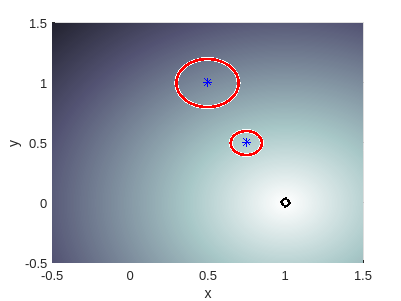

xlabel('x');
ylabel('y');
view(0, 90)
axis([-0.5 1.5 -0.5 1.5])
colormap(bone)
shading('interp')